import casadi.*

disp('=== 2. FÁZIS: CasADi MPC Szimuláció és Adatgyűjtés ===');

=== 2. FÁZIS: CasADi MPC Szimuláció és Adatgyűjtés ===



% --- ÚJ RÉSZ: TÖBB KÖR EGYMÁS UTÁN FŰZÉSE ---
korok_szama = 2; % Állítsd be, hány kört menjen! (5 kör már bőséges adatot ad)

% Mivel a pálya eleje és vége ugyanaz a pont (zárt hurok), az ismétléshez
% levágjuk az utolsó pontot, hogy ne legyen "dupla" pont a körök találkozásánál:
egy_kor_pontjai = smooth_path(1:end-1, :); 

% Megtöbbszörözzük a köröket egymás után (repmat = ismétlés)
multi_lap_path = repmat(egy_kor_pontjai, korok_szama, 1);

% A legvégére visszarakjuk az utolsó pontot, hogy a legutolsó kör is bezáruljon
multi_lap_path = [multi_lap_path; smooth_path(end, :)];
% ---------------------------------------------

Ts = 0.1; 
V_target = 5; 
N = 15; 

% FONTOS VÁLTOZÁS ITT ALÁBB: 
% Innentől a "smooth_path" helyett az új "multi_lap_path" változót használjuk 
% a referencia (RefMatrix) generálásához!

ds = sqrt(diff(multi_lap_path(:,1)).^2 + diff(multi_lap_path(:,2)).^2);
dist = [0; cumsum(ds)];
t_path = dist / V_target; 
t_sim = 0:Ts:t_path(end); 

X_ref = interp1(t_path, multi_lap_path(:,1), t_sim, 'linear', 'extrap');
Y_ref = interp1(t_path, multi_lap_path(:,2), t_sim, 'linear', 'extrap');
Vx_ref = [diff(X_ref)/Ts, 0]; 
Vy_ref = [diff(Y_ref)/Ts, 0];
RefMatrix = [X_ref', Y_ref', Vx_ref', Vy_ref'];

% ... (Innentől a kód folytatódik változatlanul az A, B mátrixokkal és a CasADi-vel) ...

% 2. Dinamika (Kettős integrátor 2D-ben)
A = [1 0 Ts 0; 0 1 0 Ts; 0 0 1 0; 0 0 0 1];
B = [0 0; 0 0; Ts 0; 0 Ts];

% 3. KISEGÍTŐ SZABÁLYOZÓ (Ancillary LQR)
Q_lqr = diag([10, 10, 1, 1]);
R_lqr = diag([0.5, 0.5]);
K_lqr = dlqr(A, B, Q_lqr, R_lqr);

% ==========================================
% 4. CASADI OPTIMIZÁCIÓS PROBLÉMA FELÉPÍTÉSE
% ==========================================
opti = casadi.Opti();

% Döntési változók (Variables) - Ezeket keresi az MPC
X = opti.variable(4, N+1); % Nominális állapotok a horizonton
U = opti.variable(2, N);   % Nominális beavatkozó jelek (gyorsulások)

% Paraméterek (Parameters) - Ezeket a szimulációs ciklusban frissítjük!
% Fontos: A paraméterek használata miatt nem kell minden lépésben újraépíteni a CasADi modellt.
x0_param = opti.parameter(4, 1);         % Aktuális nominális kezdeti állapot
ref_param = opti.parameter(4, N+1);      % Aktuális referenciatrajektória a horizontra

% --- ÚJ SOR: Ez fogadja az RL hálózat döntését ---
tube_scale_param = opti.parameter(1, 1);

% Költségfüggvény súlyok
Q_mpc = diag([100, 100, 0, 0]); % Pozíció követése a legfontosabb
R_mpc = diag([0.1, 0.1]);     % Beavatkozás simítása

cost = 0;
for k = 1:N
    % Állapothiba a referenciához képest
    err = X(:, k) - ref_param(:, k);
    
    % Kvadratikus költség növelése
    cost = cost + err' * Q_mpc * err + U(:, k)' * R_mpc * U(:, k);
    
    % Dinamikai kényszer (Shooting method: a következő pontot az A, B mátrix adja)
    opti.subject_to(X(:, k+1) == A * X(:, k) + B * U(:, k));
end
% Végső állapot költsége (Terminal cost)
err_N = X(:, N+1) - ref_param(:, N+1);
cost = cost + err_N' * Q_mpc * err_N;

opti.minimize(cost);

% Kezdeti feltétel kényszer
opti.subject_to(X(:, 1) == x0_param);

% --- TUBE TIGHTENING (Korlátok szigorítása) ---
% --- TUBE TIGHTENING (Korlátok szigorítása) ---
% Visszaállítjuk az alap tightening értéket 5-re. 
% Ez azt jelenti, hogy a nominális terv (szellemautó) csak +/- 5-ös gyorsulást használhat, 
% a maradék (25-5 = 20) erőt az LQR-re hagyjuk a szél kompenzálására.

u_tight_base = 20; 
opti.subject_to( -(u_tight_base) <= U <= (u_tight_base) );

% CasADi Solver beállítása (IPOPT a standard nonlineáris megoldó)
p_opts = struct('expand', true); % Gyorsítja a fordítást
s_opts = struct('max_iter', 100, 'print_level', 0, 'acceptable_tol', 1e-6); % Ne írja tele a konzolt
opti.solver('ipopt', p_opts, s_opts);


% ==========================================
% 5. SZIMULÁCIÓS KÖRNYEZET
% ==========================================
x_real = RefMatrix(1,:)'; % Valós kezdeti állapot
z_nom = x_real;           % Szellemautó kezdeti állapota

figure('Name', 'CasADi Tube MPC Szimuláció', 'NumberTitle', 'off');
plot(smooth_path(:,1), smooth_path(:,2), '-g', 'LineWidth', 2); hold on; grid on;
h_nom = plot(z_nom(1), z_nom(2), 'ob', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
h_real = plot(x_real(1), x_real(2), 'or', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
lgd = legend('Ideális Ív', 'CasADi Nominális', 'Valós (Zavarva)', 'Location', 'best');
lgd.AutoUpdate = 'off'; % Ez megakadályozza, hogy új elemek kerüljenek a listába!
title('CasADi Tube MPC');

real_history = []; nom_history = [];
disp('CasADi szimuláció fut... (az IPOPT megoldó dolgozik)');

CasADi szimuláció fut... (az IPOPT megoldó dolgozik)



% Inicializáljuk az x_real_prev változót a legelső állapottal
x_real_prev = x_real; 

% Létrehozzuk az üres mátrixokat az adatgyűjtéshez (hogy gyorsabb legyen a kód)
Training_Inputs = zeros(length(t_sim) - N - 1, 6);
Training_Outputs = zeros(length(t_sim) - N - 1, 4);

% 6. VEZÉRLÉSI HUROK
for k = 1 : length(t_sim) - N - 1
    
    % Jövőbeli referencia kivágása és transzponálása (4 x N+1 méretre)
    current_ref = RefMatrix(k : k+N, :)';
    
    % --- 1. LÉPÉS: CasADi Paraméterek frissítése és Megoldás ---
    opti.set_value(x0_param, z_nom);       % A nominális autó honnan indul
    opti.set_value(ref_param, current_ref);% Merre kell mennie
    
    try
        sol = opti.solve(); % IPOPT megoldó hívása
        % Kivesszük a megtervezett horizontból a legelső beavatkozást
        v_k_opt = sol.value(U(:, 1)); 
    catch
        disp('A megoldó elakadt! Az előző beavatkozást tartjuk.');
        % Ha nincs megoldás, az opti.debug.value adja a legutolsó érvényes állapotot
        v_k_opt = opti.debug.value(U(:, 1)); 
    end
    
    % --- 2. LÉPÉS: Kisegítő LQR beavatkozás ---
    % u_real = nominális + hiba kompenzáció
    u_k = v_k_opt - K_lqr * (x_real - z_nom);
    
    % Fizikai levágás a valódi hardveren (+/- 8)
    u_k = max(min(u_k, 25), -25);
    
    % --- 3. LÉPÉS: Rendszer dinamika frissítése ---
    % Szellemautó a CasADi által kiszámolt jellel:
    z_nom = A * z_nom + B * v_k_opt; 
    
    % Valós autó erős széllel/zavarással:
    %w_k = [0; 0; randn()*1.5; randn()*1.5];
    %x_real = A * x_real + B * u_k + w_k;

    % A kiszámítható fizika (Ezt az NN tökéletesen megtanulja jósolni)
    drag_x = -0.02 * x_real(3) * abs(x_real(3)) * Ts;
    drag_y = -0.02 * x_real(4) * abs(x_real(4)) * Ts;
    const_wind_x = 0.8 * Ts; 
    const_wind_y = 0.5 * Ts;

    % A véletlen szél (Ezt az LQR fogja meg, az NN nem tud vele mit kezdeni)
    zaj_x = randn() * 0;
    zaj_y = randn() * 0;

    % Győződjünk meg róla, hogy a Ts csak egy szám!
    Ts_scalar = Ts(1); 

    % Számoljuk ki az összetevőket külön, hogy lássuk, ha baj van
    w_x = const_wind_x(1) + drag_x(1) + zaj_x(1);
    w_y = const_wind_y(1) + drag_y(1) + zaj_y(1);

    % Most rakjuk össze az oszlopvektort
    w_k = [0; 0; w_x; w_y];
    
    x_real = A * x_real + B * u_k + w_k;
    
    % --- 4. Animáció frissítése ---
    real_history = [real_history; x_real'];
    nom_history = [nom_history; z_nom'];

    % Ezt tedd a ciklusod legvégére, az animáció után:

    % Kiszámoljuk, mit jósolt volna az ideális lineáris modellünk:
    x_predicted = A * x_real_prev + B * u_k; 

    % A tényleges maradék hiba (a szél/zavarás hatása):
    residual_error = x_real - x_predicted;

    % Adatok mentése a tanításhoz (minden lépésben egy új sor)
    % Bemenet: [X_poz, Y_poz, X_seb, Y_seb, U_ax, U_ay]
    Training_Inputs(k, :) = [x_real_prev', u_k']; 

    % Kimenet: A 4 állapotra vonatkozó hiba
    Training_Outputs(k, :) = residual_error';

    % Frissítjük a prev állapotot a következő lépéshez
    x_real_prev = x_real;
    
    if mod(k, 3) == 0 % Sebesség optimalizálása rajzoláskor
        set(h_nom, 'XData', z_nom(1), 'YData', z_nom(2));
        set(h_real, 'XData', x_real(1), 'YData', x_real(2));
        plot([z_nom(1), x_real(1)], [z_nom(2), x_real(2)], '-k', 'LineWidth', 0.5); 
        drawnow;
    end
end

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  19.00us (  2.71us)         7
       nlp_g  |        0 (       0)  43.00us (  6.14us)         7
  nlp_grad_f  |        0 (       0)  24.00us (  3.00us)         8
  nlp_hess_l  |        0 (       0)  11.00us (  1.83us)         6
   nlp_jac_g  |        0 (       0)  26.00us (  3.25us)         8
       total  |   1.40 s (  1.40 s)   1.40 s (  1.40 s)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  23.00us (  3.29us)         7
       nlp_g  |        0 (       0)  46.00us (  6.57us)         7
  nlp_grad_f  |        0 (       0)  31.00us (  3.87us)         8
  nlp_hess_l  |        0 (       0)  15.00us (  2.50us)         6
   nlp_jac_g  |        0 (       0)  32.00us (  4.00us)         8
       total  |  18.00ms ( 18.00ms)  17.15ms ( 17.15ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp

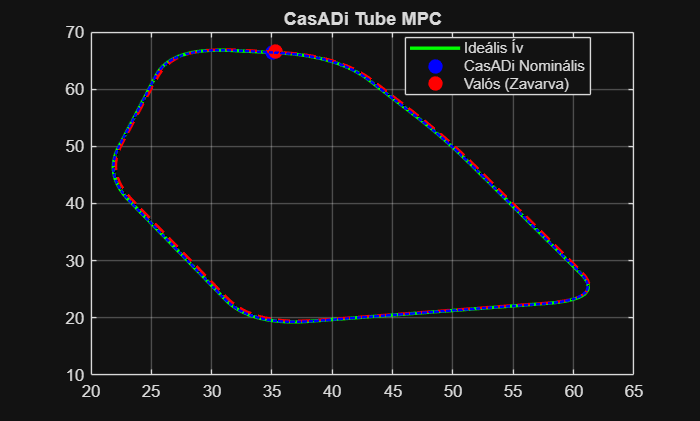


% Végső trajektóriák
plot(real_history(:,1), real_history(:,2), 'r--', 'LineWidth', 1.5);
plot(nom_history(:,1), nom_history(:,2), 'b:', 'LineWidth', 1.5);

disp('Szimuláció sikeresen befejeződött!');

Szimuláció sikeresen befejeződött!
